load flip_eqns.mat
load roll_eqns.mat
syms rw r2 r3 r5 l7_ab I7 m1 m2 m3 m4 m5 m6 m7 I1 I2 I3 I4 I5 I6 g2 C_friction7 ta13 a51 tv13 t13 T_z
design_parameters = [rw==0.075;
    r2==0.04;
    r3==0.02;
    r5==0.015;
    l7_ab==0.4;
    I7== 0.1;
    m1==0.1;
    m2==1e-10;
    m3==1e-10;
    m4==1e-10;
    m5==0.05;
    m6==0.05
    m7==0.1;
    I1==0.01;
    I2==1e-10;
    I3==1e-10;
    I4==1e-10;
    I5==0.005;
    I6==0.005;
    g2==9.81;
    C_friction7==0.1];


%apply to eqs
Q_eqn=subs(flip_eqns, lhs(design_parameters), rhs(design_parameters));
Q_eqn= ta13 == simplify(rhs(Q_eqn))


R_eqn=subs(roll_eqns, lhs(design_parameters), rhs(design_parameters))

%R_eqn= lhs(R_eqn) == simplify(rhs(R_eqn))

testeqn= ta13 == simplify(rhs(subs(Q_eqn, [tv13], [0])))

testeqn= ta13 == simplify(rhs(subs(testeqn, [t13], [0])))

$$testeqn = {\mathrm{ta}}_{13}=\frac{617500000000000000\,T_{z}+15950000000000000\,\sqrt{247}\,T_{z}-335502000335502\,\sqrt{247}-230191650276229980}{15790501009113\,\sqrt{247}+18776845830836370}$$


testeqn2= ta13 == rhs(subs(R_eqn(1), [tv13], [0]))

testeqn2= ta13 == rhs(subs(testeqn2, [t13], [0]))

$$testeqn2 = \begin{array}{l} {\mathrm{ta}}_{13}=-\frac{\sigma_{2}+\frac{187000007707\,\left(\frac{4000000000000\,T_{z}}{187000003627}-\frac{80000000000\,\left(T_{z}+\sigma_{4}+\frac{\sqrt{247}\,\left(\sigma_{2}-\frac{55917000055917}{200000000000000}\right)}{650\,\sigma_{1}\,\sigma_{3}}\right)}{187000003627\,\sigma_{5}}-\frac{3600\,\left(\sigma_{2}-\frac{55917000055917}{200000000000000}\right)}{187000003627\,\sigma_{1}\,\sigma_{3}}+\frac{600000000\,\sqrt{247}\,\left(\sigma_{2}-\frac{55917000055917}{200000000000000}\right)}{2431000047151\,\sigma_{1}\,\sigma_{3}}\right)}{720000000000\,\left(\frac{187000007707}{37400000725400000000\,\sigma_{1}\,\sigma_{3}}-\frac{187000007707\,\sqrt{247}}{2917200056581200\,\sigma_{1}\,\sigma_{3}}+\frac{187000007707\,\sqrt{247}}{1093950021217950\,\sigma_{5}\,\sigma_{1}\,\sigma_{3}}+\frac{80}{9}\right)}-\frac{55917000055917}{200000000000000}}{\sigma_{1}\,\sigma_{3}}\\ \mathrm{where}\\ \sigma_{1}=\frac{187000007707}{19200000000000\,\sigma_{3}}-1\\ \sigma_{2}=\frac{43\,\left(T_{z}+\sigma_{4}\right)}{400\,\sigma_{5}}\\ \sigma_{3}=\frac{43\,\sqrt{247}}{260000\,\sigma_{5}}-\frac{3\,\sqrt{247}}{416000}+\frac{54956004331601}{2400000000000000}\\ \sigma_{4}=\frac{981\,\sqrt{247}}{80000}\\ \sigma_{5}=\frac{\sqrt{247}}{40}+\frac{3}{400} \end{array}$$

testeqn2= ta13 == simplify(rhs(testeqn2))

$$testeqn2 = {\mathrm{ta}}_{13}=\frac{7075083871718117436654367260671083903461350000000000000\,T_{z}}{216260790022704775842825123669911646905797889835690429}+\frac{177752989392194136458174424175825359928000000000000000\,\sqrt{247}\,T_{z}}{216260790022704775842825123669911646905797889835690429}-\frac{77849930820622631285523329335219292530530000000000\,\sqrt{247}}{10298132858224036944896434460471983185990375706461449}-\frac{126232093915726752457306209197603540560270785768646446}{10298132858224036944896434460471983185990375706461449}$$

%create plot of required torque vs position
P_eqn=subs(Q_eqn, [tv13, ta13], [0, 0])

P_eqn=isolate(P_eqn, T_z)

$$P\_eqn = \begin{array}{l} T_{z}=\frac{\frac{16821697520186037\,\cos\left(t_{13}\right)\,\sigma_{2}}{1600}+210271218750\,\sin\left(t_{13}\right)\,\sigma_{2}+\frac{3187269003187269\,\sqrt{19}\,\cos\left(t_{13}\right)\,\sigma_{3}}{3200}+\frac{20186037020186037\,\sqrt{19}\,\sin\left(2\,t_{13}\right)\,\sigma_{1}}{32000}}{2226562500000\,\sqrt{19}\,\sigma_{1}+28203125000000\,\sigma_{2}+45125000000000\,\sqrt{19}\,\cos\left(t_{13}\right)\,\sigma_{3}-1692187500000\,\sqrt{19}\,\sin\left(t_{13}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}={\left(-19\,{\sin\left(t_{13}\right)}^{2}-30\,\sin\left(t_{13}\right)+325\right)}^{3/2}\\ \sigma_{2}={\left(19\,{\sin\left(t_{13}\right)}^{2}+30\,\sin\left(t_{13}\right)-325\right)}^{2}\\ \sigma_{3}={\left(19\,{\cos\left(t_{13}\right)}^{2}-30\,\sin\left(t_{13}\right)+306\right)}^{3/2} \end{array}$$

xvals=linspace(0, pi/2, 100)

xvals =          0    0.0159    0.0317    0.0476    0.0635    0.0793    0.0952    0.1111    0.1269    0.1428    0.1587    0.1745    0.1904    0.2063    0.2221    0.2380    0.2539    0.2697    0.2856    0.3015    0.3173    0.3332    0.3491    0.3649    0.3808    0.3967    0.4125    0.4284    0.4443    0.4601    0.4760    0.4919    0.5077    0.5236    0.5395    0.5553    0.5712    0.5871    0.6029    0.6188    0.6347    0.6505    0.6664    0.6823    0.6981    0.7140    0.7299    0.7457    0.7616    0.7775


yvals = linspace(0, 0, 100)

yvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


syms Tf(t13)
Tf(t13) = rhs(P_eqn)

$$Tf(t13) = \begin{array}{l} \frac{\frac{16821697520186037\,\cos\left(t_{13}\right)\,\sigma_{2}}{1600}+210271218750\,\sin\left(t_{13}\right)\,\sigma_{2}+\frac{3187269003187269\,\sqrt{19}\,\cos\left(t_{13}\right)\,\sigma_{3}}{3200}+\frac{20186037020186037\,\sqrt{19}\,\sin\left(2\,t_{13}\right)\,\sigma_{1}}{32000}}{2226562500000\,\sqrt{19}\,\sigma_{1}+28203125000000\,\sigma_{2}+45125000000000\,\sqrt{19}\,\cos\left(t_{13}\right)\,\sigma_{3}-1692187500000\,\sqrt{19}\,\sin\left(t_{13}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}={\left(-19\,{\sin\left(t_{13}\right)}^{2}-30\,\sin\left(t_{13}\right)+325\right)}^{3/2}\\ \sigma_{2}={\left(19\,{\sin\left(t_{13}\right)}^{2}+30\,\sin\left(t_{13}\right)-325\right)}^{2}\\ \sigma_{3}={\left(19\,{\cos\left(t_{13}\right)}^{2}-30\,\sin\left(t_{13}\right)+306\right)}^{3/2} \end{array}$$

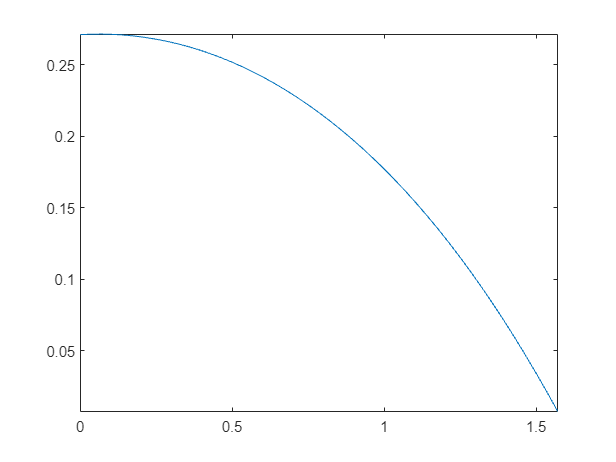

fplot(Tf(t13), [0, pi/2])


%for i = 1:100
%    yvals=rhs(subs(P_eqn, t13, xvals(i)))
%end
%plot(xvals, yvals)

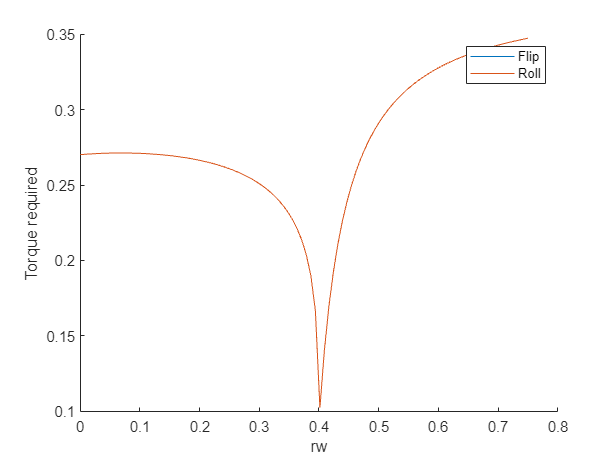


hold off


xvals=zeros(length(design_parameters),100)

xvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

yvals=zeros(length(design_parameters),100)

yvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

yvals2=zeros(length(design_parameters),100)

yvals2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

i = 2

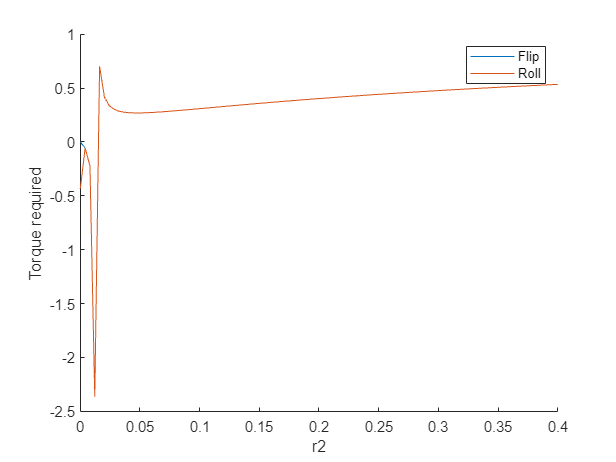

for i=1:length(design_parameters)
    P_eqn=subs(flip_eqns, lhs(design_parameters(1:end ~=i)), rhs(design_parameters(1:end ~=i)));
    P_eqn=subs(P_eqn, [tv13, ta13, t13], [0, 0, 0]);
    P_eqn=isolate(P_eqn, T_z);
    xvals(i,:)=linspace(1e-10, 10*rhs(design_parameters(i)), 100);

    for k = 1:100
        try
            yvals(i,k)=real(simplify(rhs(subs(P_eqn, lhs(design_parameters(i)), xvals(i,k)))));
        catch 
        end
    end

    P_eqn=subs(roll_eqns(1), lhs(design_parameters(1:end ~=i)), rhs(design_parameters(1:end ~=i)));
    P_eqn=subs(P_eqn, [tv13, ta13, t13], [0, 0, 0]);
    P_eqn=isolate(P_eqn, T_z);

    for k = 1:100
        try
            yvals2(i,k)=real(simplify(rhs(subs(P_eqn, lhs(design_parameters(i)), xvals(i,k)))));
        catch 
        end
    end

    figure
    hold on
    plot(xvals(i,:), yvals(i,:))
    plot(xvals(i,:), yvals2(i,:))
    ylabel("Torque required")
    xlabel(string(lhs(design_parameters(i))))
    legend('Flip', 'Roll')
    hold off

end    